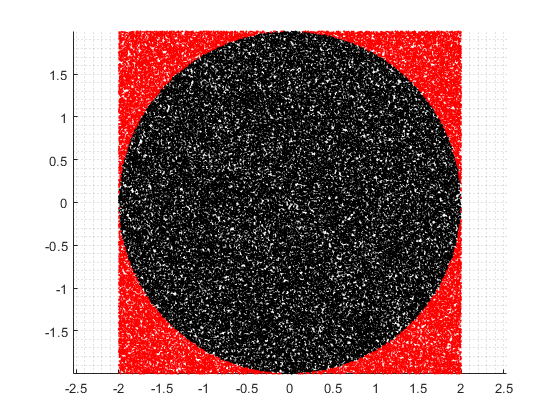

clear variables; close all; clc

N = 1e5;
radius = 2;
square_area = (2 * radius)^2;
pts = rand(N, 2) * (2 * radius) - radius;
in_circle = vecnorm(pts, 2, 2) <= radius;
circle_area_hat = sum(in_circle) / N * square_area;
pi_hat = circle_area_hat / radius^2;

figure
hold on; grid minor;
scatter(pts(in_circle, 1), pts(in_circle, 2), 1, 'k')
scatter(pts(~in_circle, 1), pts(~in_circle, 2), 1, 'r')
axis('equal');

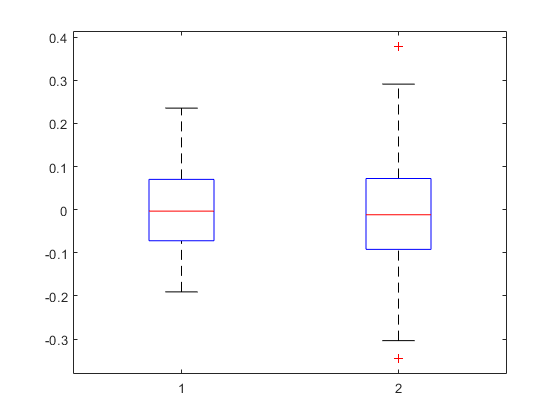

% target normale N(0,1)
% proposal uniforme U(-1,1)

n = 100;

mu = nan(n,1);
mu_r = nan(n,1);

for mm = 1:100
x = rand(1,n) * 6 - 3;

w = nan(1,n);
for ii = 1 : n
    w(ii) = normpdf(x(ii), 0, 1) / (1/6);
end

w = w/sum(w);

mu(mm) = w*x';

xr = x(multinomial_sampling(w,n));
wr = ones(1,n)/n;

mu_r(mm) = xr*wr';
end

figure
boxplot([mu mu_r]);

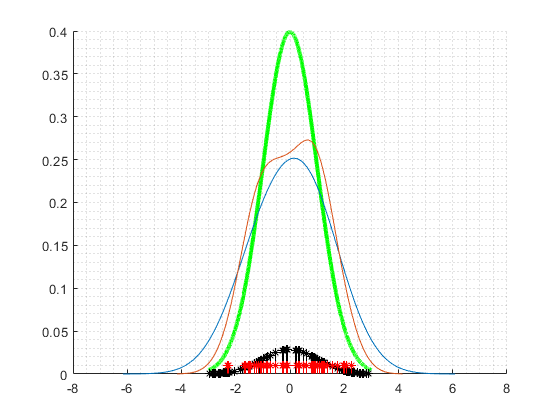


xx = linspace(-3, 3, 10000 );
yy = normpdf(xx,0,1);

figure; hold on; grid minor;
plot(xx,yy, 'g', 'LineWidth',3);
ksdensity(x, 'weights', w);
ksdensity(xr);
stem(x, w, 'k*');
stem(xr, wr, 'r*');